# Evaluation of the models

We have just finished training a model, and as we’ve seen, YOLOv8 allows the use of many different parameters during training. Now, we could train another YOLOv8 model with different parameters. But this raises two important questions: **How can we determine if our current model performs well, or if we need to train a new one? And how can we compare multiple models to decide which one is the best?**

To answer these questions, we rely on **evaluation metrics**. Below, we will explain the most widely used metrics for **object detection.**

addpath('installation-module');

### Intersection over Union (IoU) 

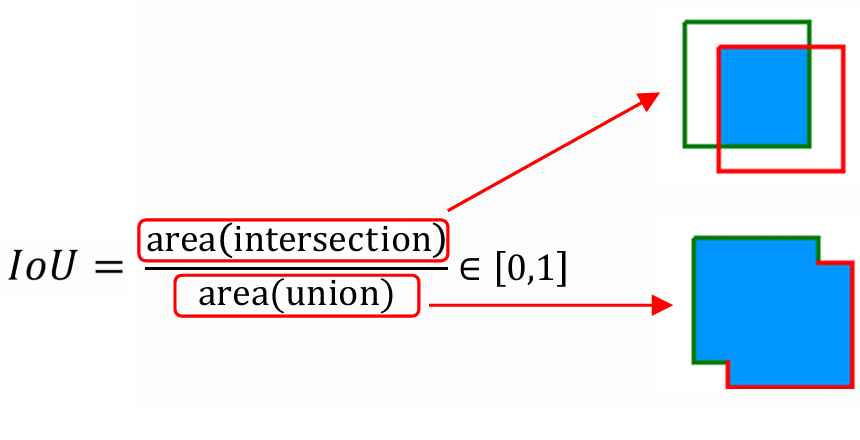

#### Exercise calculate IoU:

function iou = calculateIoU(b1, b2)

    x1 = max(b1(1), b2(1));
    y1 = max(b1(2), b2(2));
    x2 = min(b1(3), b2(3));
    y2 = min(b1(4), b2(4));
    inter = max(0, x2-x1) * max(0, y2-y1);

Loading Model....


    area1 = (b1(3)-b1(1))*(b1(4)-b1(2));
    area2 = (b2(3)-b2(1))*(b2(4)-b2(2));

Model loaded


    union = area1 + area2 - inter;

    if union>0
        iou = inter/union;
    else
        iou = 0;
    end
   
end

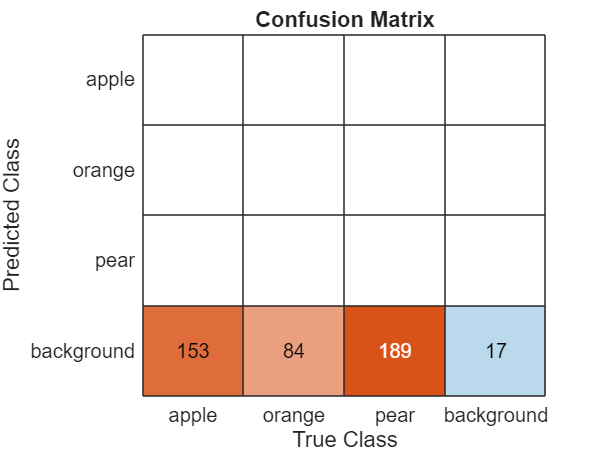

datasetFolder = "datasets/fruits_3_4998/";    
splitFolder = datasetFolder + "val";
modelPath = fullfile(pwd, 'runs', 'detect', 'train10', 'weights');
configFile  = datasetFolder + "data.yaml";
classNames =  utils.ReadClassNames(configFile);


disp("Loading Model....");
model = utils.loadModel(modelPath, configFile);
disp("Model loaded");
predictions = utils.getPredictions(model, splitFolder, classNames);

### Confusion matrix

classNames =  utils.ReadClassNames(configFile);
scoreThreshold = 0.9;
iouThreshold = 0.6;

confMat = utils.computeConfusionMatrix(predictions, classNames, scoreThreshold, iouThreshold, @calculateIoU);

allClassNames = [classNames(:); {'background'}];

utils.displayConfusionMatrix(confMat, allClassNames)

     ClassName      True Positive
    ____________    _____________

    "apple"              152     
    "orange"              81     
    "pear"               154     
    "background"          17     



### Exercise: Extract TP, FP, FN of each class

function [TP, FP, FN] = extractConfusionMatrixValues(confusionMat)

     ClassName      False Positive
    ____________    ______________

    "apple"                3      
    "orange"               5      
    "pear"               172      
    "background"          36      



    numClasses = size(confusionMat, 1);

     ClassName      False Negative
    ____________    ______________

    "apple"                1      
    "orange"               3      
    "pear"                35      
    "background"         177      



    TP = zeros(numClasses, 1);
    FP = zeros(numClasses, 1);
    FN = zeros(numClasses, 1);
    for i = 1:numClasses
        TP(i) = confusionMat(i, i);
        FP(i) = sum(confusionMat(i, :)) - TP(i);
        FN(i) = sum(confusionMat(:, i)) - TP(i);
    end
end


[TP, FP, FN] = extractConfusionMatrixValues(confMat);


tableTP = table(string(allClassNames), TP, 'VariableNames', {'ClassName', 'True Positive'});

     ClassName      Precision
    ____________    _________

    "apple"          0.98065 
    "orange"         0.94186 
    "pear"           0.47239 
    "background"     0.32075 
    "Overall"        0.67891 



tableFP = table(string(allClassNames), FP, 'VariableNames', {'ClassName', 'False Positive'});
tableFN = table(string(allClassNames), FN, 'VariableNames', {'ClassName', 'False Negative'});

disp(tableTP)
disp(tableFP)
disp(tableFN)

### Precision

Measures the accuracy of the model in a class.  Proportion of true positives relative to the total number of assigned positives. Mathematically:


$$\textrm{Precision}=\frac{\textrm{TP}}{\textrm{TP}+\textrm{FP}}$$


Hay diferentes formas de calcular la precision, se puede calcular la precision de cada una de las clases, se puede calcular la precision total y una precision balanceada por clases.

Exercise. Crea una función para calcular la precision de cada clase y la precision total

Remember (/) divide matricialmente. (./) divide por elementos 

function precision = precisionFunc(TP, FP)
    
    denom = (TP + FP);


     ClassName       Recall 
    ____________    ________

    "apple"          0.99346
    "orange"         0.96429
    "pear"           0.81481
    "background"    0.087629
    "Overall"        0.71505



    precision = TP ./ denom;
    totalTP = sum(TP);
    total = totalTP + sum(FP);
    
    if total == 0
        total = NaN;
    end
    
    precisionMacro = sum(precision) / length(precision);
    totalPrecision =  totalTP / total;
    precision = [precision; precisionMacro];
    
end

    {'apple'}    {'orange'}    {'pear'}

     0

    0.0500

    0.1000

    0.1500

    0.2000

    0.2500

    0.3000

    0.3500

    0.4000

    0.4500

    0.5000

    0.5500

    0.6000

    0.6500

    0.7000

    0.7500

    0.8000

    0.8500

    0.9000

    0.9500

     1

     1    21



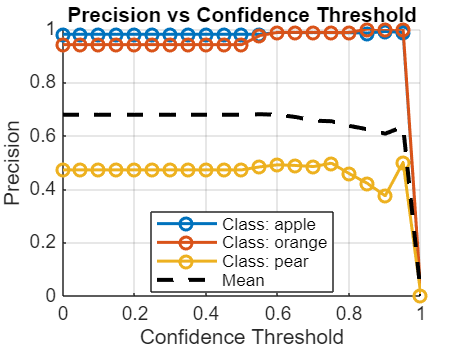

precision = precisionFunc(TP, FP);

metricsClassNames = string([allClassNames(:); {'Overall'}]);
precisionTable = table(metricsClassNames, precision, 'VariableNames', {'ClassName', 'Precision'});
disp(precisionTable)

### Recall

Measures the sensitivity of the model to detect a class. Ratio of true positives to the total number of actual positives. Mathematically:


$$\textrm{Recall}=\frac{\textrm{TP}}{\textrm{TP}+\textrm{FN}}$$


    {'apple'}    {'orange'}    {'pear'}

     0

    0.0500

    0.1000

    0.1500

    0.2000

    0.2500

    0.3000

    0.3500

    0.4000

    0.4500

    0.5000

    0.5500

    0.6000

    0.6500

    0.7000

    0.7500

    0.8000

    0.8500

    0.9000

    0.9500

     1

     1    21



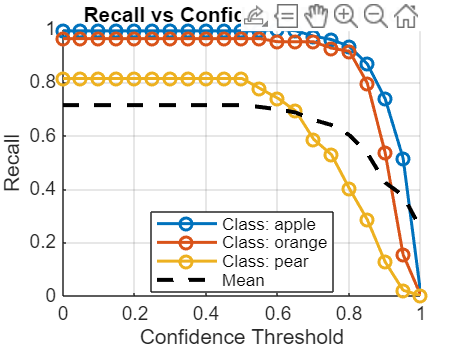

function recall = recallFunc(TP, FN)  

    recall = precisionFunc(TP, FN);
    
end

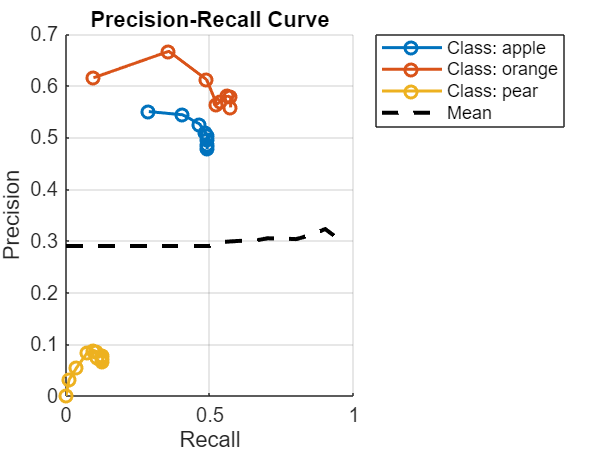

ans = 0.2088

recall = recallFunc(TP, FN);


recallTable = table(metricsClassNames, recall, 'VariableNames', {'ClassName', 'Recall'});
disp(recallTable)

### Precision/Recall Trade off

There is usually a trade-off between precision and recall, where better precision means lower recall and vice versa.

This is because precision measures not missing anything, while recall measures not leaving anything out.

### Precision / Confidence

function plotPrecisionConfidence = plotPrecisionConfidence(predictions, classNames, confMatFunc, extractConfMatValuesFunc, iouThreshold)  
    step_size = 0.05;

logdir = 'C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision'

    steps = 1/step_size + 1;   
    disp(classNames)
    numClasses = numel(classNames);

start "" "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision\win64\python\python" -m tensorboard.main --logdir "C:\Users\Noel Nathan\Desktop\Universidad\8tQuadrimestre\tfg\from-code-to-robot\computer_vision"



    precision = zeros(steps, numClasses +2);


✅ TensorBoard is running in the background...


    for i = 1:steps
        scoreThreshold = (i - 1) * step_size;
        disp(scoreThreshold);
        confMat = confMatFunc(predictions, classNames, scoreThreshold, iouThreshold, @calculateIoU);
        [TP, FP, FN] = extractConfMatValuesFunc(confMat);
        precisionTemp  = precisionFunc(TP, FP);
        precisionTemp(isnan(precisionTemp)) = 0;
        precision(i, :) = precisionTemp;
        confidence(i) = scoreThreshold;
    end
    figure;
    hold on;
    disp(size(confidence))
    colors = lines(numClasses);
    for c = 1:numClasses
        plot(confidence, precision(:, c), '-o', 'Color', colors(c,:), 'LineWidth', 1.5, ...
             'DisplayName', sprintf('Class: %s', classNames{c}));
    end
    % Last Column, avg
    plot(confidence, precision(:, end), '--k', 'LineWidth', 2, 'DisplayName', 'Mean');
    hold off;
    
    grid on;
    xlabel('Confidence Threshold');
    ylabel('Precision');
    title('Precision vs Confidence Threshold');
    legend('Location', 'best');
end

plotPrecisionConfidence(predictions, classNames, @utils.computeConfusionMatrix, @extractConfusionMatrixValues, 0.6)  

function plotRecallConfidence = plotRecallConfidence(predictions, classNames, confMatFunc, extractConfMatValuesFunc, iouThreshold)  
    step_size = 0.05;
    steps = 1/step_size + 1;   
    disp(classNames)
    numClasses = numel(classNames);

    precision = zeros(steps, numClasses +2);

    for i = 1:steps
        scoreThreshold = (i - 1) * step_size;
        disp(scoreThreshold);
        confMat = confMatFunc(predictions, classNames, scoreThreshold, iouThreshold, @calculateIoU);
        [TP, FP, FN] = extractConfMatValuesFunc(confMat);
        precisionTemp  = recallFunc(TP, FN);
        precisionTemp(isnan(precisionTemp)) = 0;
        precision(i, :) = precisionTemp;
        confidence(i) = scoreThreshold;
    end
    figure;
    hold on;
    disp(size(confidence))
    colors = lines(numClasses);
    for c = 1:numClasses
        plot(confidence, precision(:, c), '-o', 'Color', colors(c,:), 'LineWidth', 1.5, ...
             'DisplayName', sprintf('Class: %s', classNames{c}));
    end
    % Last Column, avg
    plot(confidence, precision(:, end), '--k', 'LineWidth', 2, 'DisplayName', 'Mean');
    hold off;
    
    grid on;
    xlabel('Confidence Threshold');
    ylabel('Recall');
    title('Recall vs Confidence Threshold');
    legend('Location', 'best');
end

plotRecallConfidence(predictions, classNames, @utils.computeConfusionMatrix, @extractConfusionMatrixValues, 0.6)  

function meanAUC =  precisionRecallCurve(predictions, classNames, confMatFunc, extractConfMatValuesFunc, iouThreshold, showPlot)
    % Parámetros
    step_size = 0.05;
    steps = 1/step_size + 1;   
    numClasses = numel(classNames);

    % Inicialización
    precision = zeros(steps, numClasses +2);
    recall    = zeros(steps, numClasses +2);
    confidence = zeros(steps, 1);

    % Bucle por umbral de confianza
    for i = 1:steps
        scoreThreshold = (i - 1) * step_size;
        confidence(i) = scoreThreshold;

        % Calcular matriz de confusión para este umbral
        confMat = confMatFunc(predictions, classNames, scoreThreshold, iouThreshold, @calculateIoU);
        [TP, FP, FN] = extractConfMatValuesFunc(confMat);

        precision(i, :) = precisionFunc(TP, FP);
        recall(i, :)    = precisionFunc(TP, FN);
    end

    auc = zeros(1, numClasses);
    for c = 1:numClasses
        [sortedRecall, idx] = sort(recall(2:end, c));
        sortedPrecision = precision(idx, c);
        auc(c) = trapz(sortedRecall, sortedPrecision);
    end
    meanAUC = mean(auc);
    
    if showPlot
        figure;
        hold on;
        colors = lines(numClasses);
        for c = 1:numClasses
            plot(recall(:, c), precision(:, c), '-o', 'Color', colors(c,:), 'LineWidth', 1.5, ...
                'DisplayName', sprintf('Class: %s', classNames{c}));
        end
    
        plot(confidence, precision(:, end), '--k', 'LineWidth', 2, 'DisplayName', 'Mean');
        hold off;
        
    
        grid on;
        xlabel('Recall');
        ylabel('Precision');
        title('Precision-Recall Curve');
        legend('Location', 'northeastoutside');
        hold off;
    end
end

precisionRecallCurve(predictions, classNames, @utils.computeConfusionMatrix, @extractConfusionMatrixValues, 0.9, true)  


### Precision-Recall curve

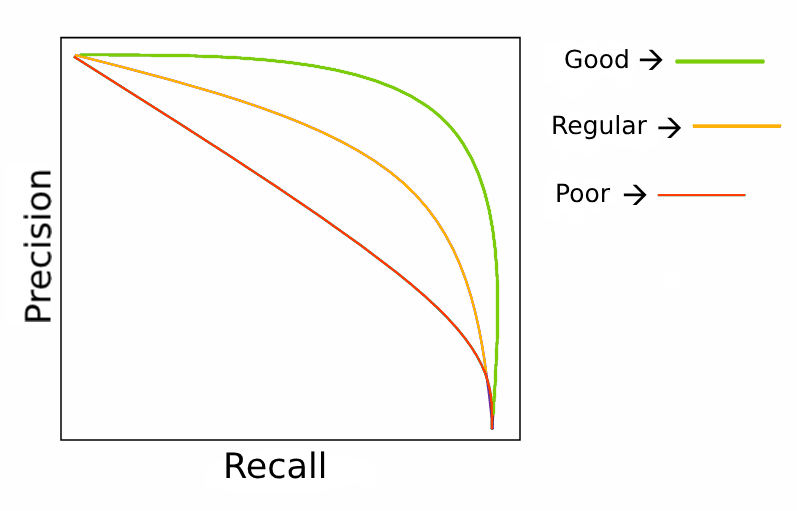

### Curva Receiver Operating Characteristic (ROC) 

### F1-score

F1-score is a metric that takes recall and precision into account in its value:


$${\textrm{f1}}_{\textrm{score}} =\frac{2\cdot \textrm{presicion}\cdot \textrm{recall}}{\textrm{precision}+\textrm{recall}}$$


## All together

http://localhost:6006/

pyInterpreter = char(getPythonInterpreter());
logdir = fullfile(pwd)
command = ['start "" "' pyInterpreter '" -m tensorboard.main --logdir "' logdir '"'];

disp(command) 
system(command); 

disp('✅ TensorBoard is running in the background...');